clc; close all; clear all;

y_1_name = "y1.wav";
y_2_name = "y2.wav";
s_1_name = "Doimo_Ostan_s1_hat.wav";
s_2_name = "Doimo_Ostan_s2_hat.wav";
s_3_name = "Doimo_Ostan_s3_hat.wav";
% reference signal names

s_1_ref_name = "s1.wav"; 
s_2_ref_name = "s2.wav"; 
s_3_ref_name = "s3.wav"; 


if not(isfolder("audioOutputs"))
    mkdir("audioOutputs")
end

addpath('audioInputs')
addpath('audioOutputs')

[y_1_t,y_1_Fs] = audioread(y_1_name);
[y_2_t,y_2_Fs] = audioread(y_2_name);
[s_1_ref_t,s_1_ref_Fs] = audioread(s_1_ref_name);
[s_2_ref_t,s_2_ref_Fs] = audioread(s_2_ref_name);
[s_3_ref_t,s_3_ref_Fs] = audioread(s_2_ref_name);
y_1_t_len = length(y_1_t);
y_2_t_len = length(y_2_t);

M=512

M = 512

R=M/2

R = 256

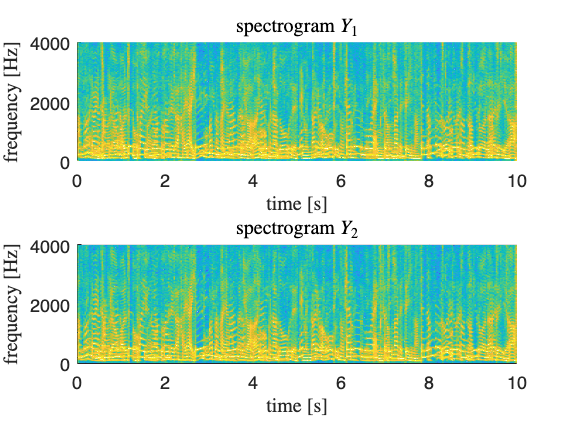

y_1_st_w = mystft(y_1_t,"hann",M,R);
y_2_st_w = mystft(y_2_t,"hann",M,R);


%log-amplitude spectrograms for the mixture signals (subplot).
figure 
w1 = linspace(0,y_1_Fs/2,M/2);
t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
y_11_st_w = y_1_st_w(1:M/2,:);
y_22_st_w = y_2_st_w(1:M/2,:);
subplot(2,1,1)
surf(t,w1,log(abs(y_11_st_w)./(max(abs(y_11_st_w)))),EdgeColor="none");

%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $ Y_1$',Interpreter='Latex');

subplot(2,1,2)
surf(t,w1,log(abs(y_22_st_w)./(max(abs(y_22_st_w)))),EdgeColor="none");

%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $ Y_2$',Interpreter='Latex');

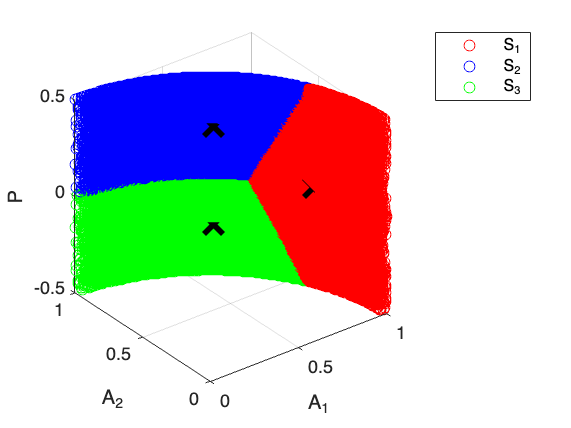


y_1_w_lin = reshape(y_1_st_w,size(y_1_st_w,1)*size(y_1_st_w,2),1);
y_2_w_lin = reshape(y_2_st_w,size(y_2_st_w,1)*size(y_2_st_w,2),1);




if(length(y_2_w_lin) ~= length(y_1_w_lin))
    disp("error between microphones signal length")
end




FI = zeros(length(y_1_w_lin),3);

% compute first and feature
for ii = 1:length(y_1_w_lin)
   Y_1 = y_1_w_lin(ii);
   Y_2 = y_2_w_lin(ii);
   root_sum = (sqrt(abs(Y_1)^2 + abs(Y_2)^2));
   A_1 = abs(Y_1) / root_sum;
   A_2 = abs(Y_2) / root_sum;
   P = 1/(2*pi) * angle(Y_2/Y_1);
   
   %P_1 = 1/(2*pi) * angle(Y_2/Y_1);
   %P_2 = 1/(2*pi) * angle(Y_1/Y_2);
   FI(ii,1) = A_1;
   FI(ii,2) = A_2;
   FI(ii,3) = P;
   %FI(ii,3) = P_1;
   %FI(ii,4) = P_2;
end

[idx,C] = kmeans(FI,3);

%idx = kmeans(FI,3,"Distance","correlation","Start","cluster");
figure
scatter3(FI(idx==1,1),FI(idx==1,2),FI(idx==1,3),'ro')
hold on
scatter3(FI(idx==2,1),FI(idx==2,2),FI(idx==2,3),'bo')
hold on
scatter3(FI(idx==3,1),FI(idx==3,2),FI(idx==3,3),'go')
hold on 
plot3(C(:,1),C(:,2),C(:,3),'kx',...
     'MarkerSize',15,'LineWidth',3) 
xlabel("A_1")
ylabel("A_2")
zlabel("P")
legend("S_1","S_2","S_3")

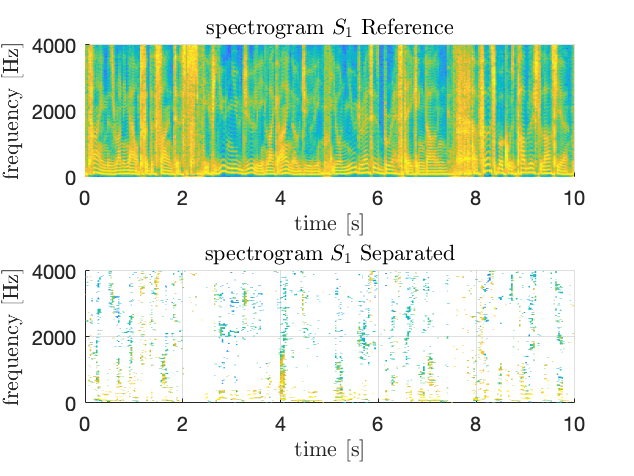

%density plot A_1 A_2
%figure 
%surf()


M_1_lin = zeros(length(idx),1);
M_2_lin = zeros(length(idx),1);
M_3_lin = zeros(length(idx),1);
for ii = 1: length(idx)
    if idx(ii) == 1
        M_1_lin(ii) = 1;
    elseif idx(ii) == 2
        M_2_lin(ii) = 1;
    elseif idx(ii) == 3
        M_3_lin(ii) = 1;
    end
end

%M_1 = reshape(M_1_lin,size(y_1_st_w,1),size(y_1_st_w,2));
%M_2 = reshape(M_2_lin,size(y_1_st_w,1),size(y_1_st_w,2));
%M_3 = reshape(M_3_lin,size(y_1_st_w,1),size(y_1_st_w,2));

S_1_lin = y_1_w_lin .* M_1_lin;
S_2_lin = y_1_w_lin .* M_2_lin;
S_3_lin = y_1_w_lin .* M_3_lin;

S_1 = reshape(S_1_lin,size(y_1_st_w,1),size(y_1_st_w,2));
S_2 = reshape(S_2_lin,size(y_1_st_w,1),size(y_1_st_w,2));
S_3 = reshape(S_3_lin,size(y_1_st_w,1),size(y_1_st_w,2));

s_1_t = myistft(S_1,M,R);
s_2_t = myistft(S_2,M,R);
s_3_t = myistft(S_3,M,R);

chosen_ref = zeros(1,3);
for i=1:3
    max_val_corr = 0;
    for j=1:3
        corr = abs(max(xcorr(eval(strcat("s_",num2str(i), "_t")),eval(strcat("s_",num2str(j), "_ref_t")))));
        if(corr>max_val_corr)
            chosen_ref(1,i) = j;
            max_val_corr=corr;
        end
    end
end

% works but to be better implemented when the value 
% log-amplitude spectrograms of the true and estimated source signals (subplots).
% SIGNAL 1

% load and process reference 1
s_1_ref_st_w = mystft(s_1_ref_t,"hann",M,R);
s_2_ref_st_w = mystft(s_2_ref_t,"hann",M,R);
s_3_ref_st_w = mystft(s_3_ref_t,"hann",M,R);

figure 
w1 = linspace(0,y_1_Fs/2,M/2);
t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_11_ref = s_1_ref_st_w(1:M/2,:);
S_11 = S_1(1:M/2,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_11_ref)./(max(abs(S_11_ref)))),EdgeColor="none");
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_1$ Reference',Interpreter='Latex');
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_11)./(max(abs(S_11)))),EdgeColor="none");

view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_1$ Separated',Interpreter='Latex');

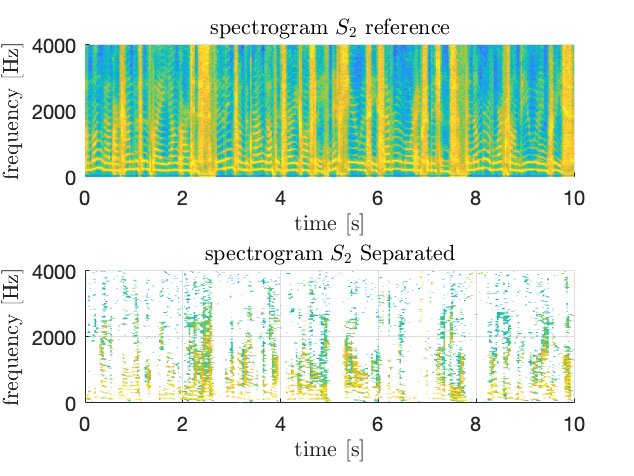


%Source 2
figure 
w1 = linspace(0,y_1_Fs/2,M/2);
t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_22_ref = s_2_ref_st_w(1:M/2,:);
S_22 = S_2(1:M/2,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_22_ref)./(max(abs(S_22_ref)))),EdgeColor="none");
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_2$ reference',Interpreter='Latex');
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_22)./(max(abs(S_22)))),EdgeColor="none");

view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_2$ Separated',Interpreter='Latex');

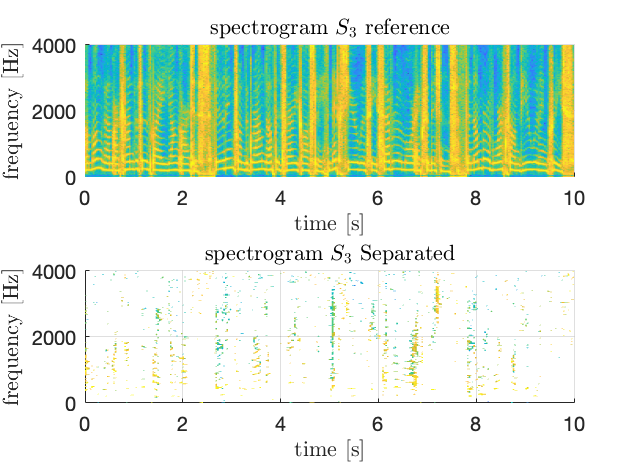

%Source 3
figure 
w1 = linspace(0,y_1_Fs/2,M/2);
t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_33_ref = s_3_ref_st_w(1:M/2,:);
S_33 = S_3(1:M/2,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_33_ref)./(max(abs(S_33_ref)))),EdgeColor="none");
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_3$ reference',Interpreter='Latex');
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_33)./(max(abs(S_33)))),EdgeColor="none");

view(0,90);
xlabel("time [s]",Interpreter="latex");
ylabel("frequency [Hz]",Interpreter="latex");
title('spectrogram $S_3$ Separated',Interpreter='Latex');


%for nn = 1:size(S_1,2)
%    S_1(M+1:2*M+1,nn) = 0;
%    S_2(M+1:2*M+1,nn) = 0;
%    S_3(M+1:2*M+1,nn) = 0;
%end



audiowrite("./audioOutputs/"+s_1_name,real(s_1_t)/max(real(s_1_t)),y_1_Fs);
audiowrite("./audioOutputs/"+s_2_name,real(s_2_t)/max(real(s_2_t)),y_1_Fs);

audiowrite("./audioOutputs/"+s_3_name,real(s_3_t)/max(real(s_3_t)),y_1_Fs);